# Simulating light propagation

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

Acknoledgement: the author would like to thank the developers of MCMatlab software. 

## Simulating data collection for one PPG pulse

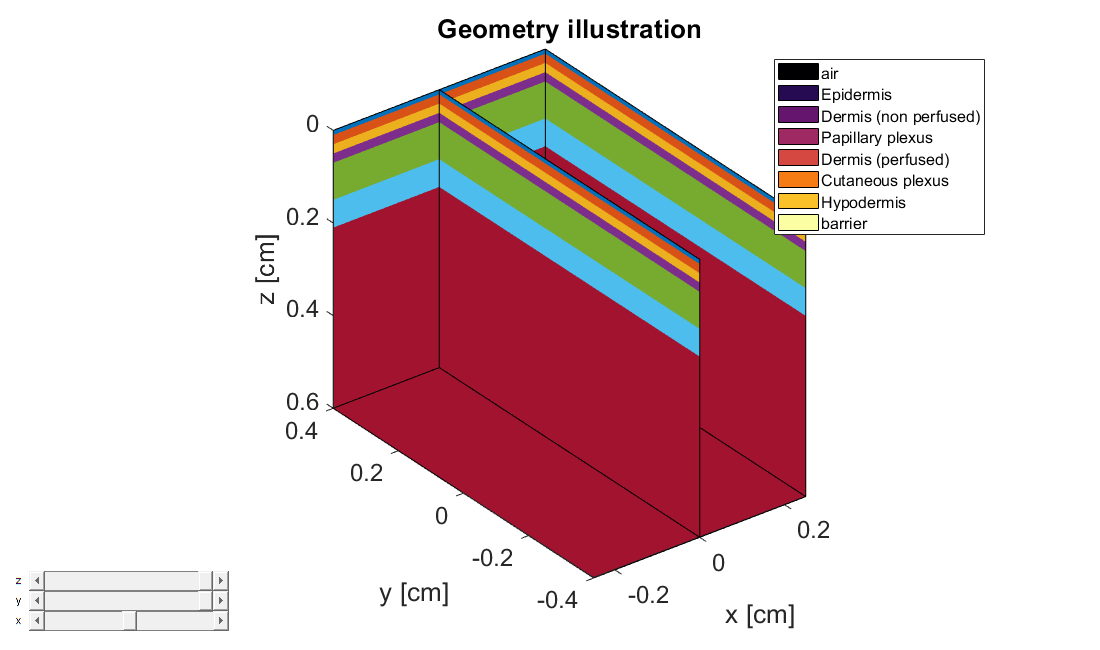

-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.44e+07 photons at a rate of 2.44e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.41e+07 photons at a rate of 2.41e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.41e+07 photons at a rate of 2.41e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.40e+07 photons at a rate of 2.40e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.42e+07 photons at a rate of 2.42e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 


Simulated 2.71e+07 photons at a rate of 2.66e+06 photons per minute


-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating...   0% done

  2% done

  3% done

100% done
Simulated 2.38e+07 photons at a rate of 2.38e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.48e+07 photons at a rate of 2.48e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.42e+07 photons at a rate of 2.42e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.68e+07 photons at a rate of 2.68e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.77e+07 photons at a rate of 2.77e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.69e+07 photons at a rate of 2.69e+06 photons per minute
--

% Fig 7.10 Simulation
% The air gap of 0.01 mm
clear all
global zsurf;
zsurf=0.01;
Example4_BloodVessel_Pulse
for i=1:38;
    model = runMonteCarlo(model);
    
    %plotMCmatlab(model);
    if model.MC.LC.res > 1
        detFraction = 100*mean(mean(sum(model.MC.LC.image,3)))*model.MC.LC.fieldSize^2;
    else
        detFraction = 100*sum(model.MC.LC.image,3);
    end  
    S(i)=detFraction;
end

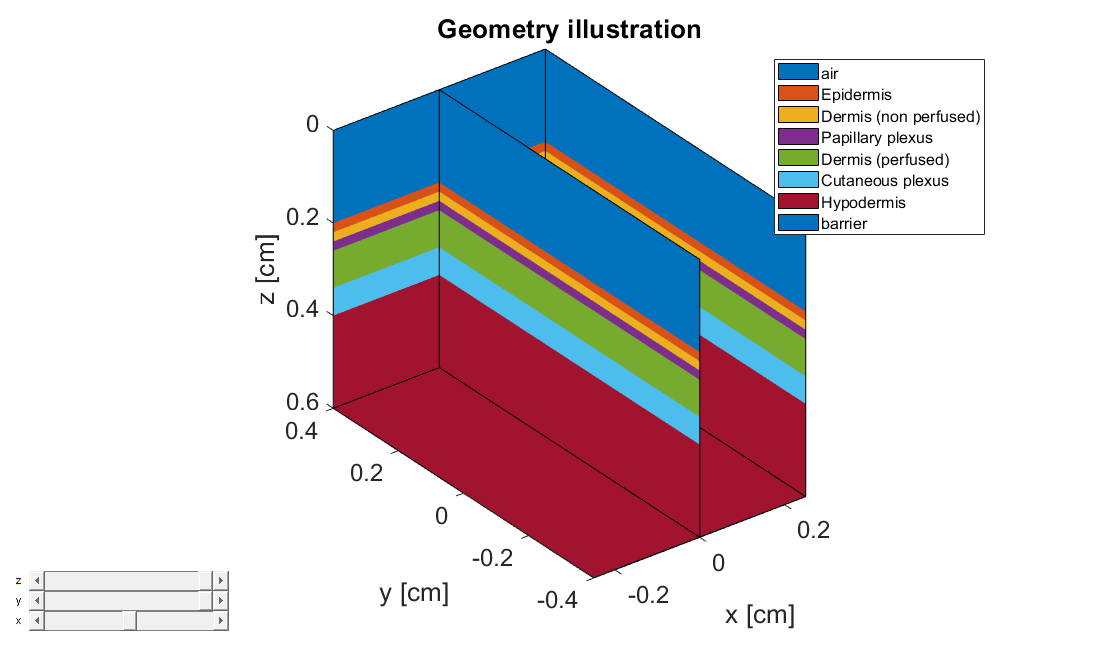

save('SPulse_660_001_1.mat','S')
% Increasing the air gap to 0.2 mm
clear all
global zsurf;
zsurf=0.2;
Example4_BloodVessel_Pulse

for i=1:38;
    model = runMonteCarlo(model);
    
    %plotMCmatlab(model);
    if model.MC.LC.res > 1
        detFraction = 100*mean(mean(sum(model.MC.LC.image,3)))*model.MC.LC.fieldSize^2;
    else
        detFraction = 100*sum(model.MC.LC.image,3);
    end  
    S(i)=detFraction;
end

-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.92e+07 photons at a rate of 1.92e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.80e+07 photons at a rate of 1.80e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.79e+07 photons at a rate of 1.79e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.83e+07 photons at a rate of 1.83e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.82e+07 photons at a rate of 1.82e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 

100% done
Simulated 1.92e+07 photons at a rate of 1.92e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.87e+07 photons at a rate of 1.87e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.83e+07 photons at a rate of 1.83e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 1.91e+07 photons at a rate of 1.91e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.14e+07 photons at a rate of 2.14e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.10e+07 photons at a rate of 2.10e+06 photons per minute
--

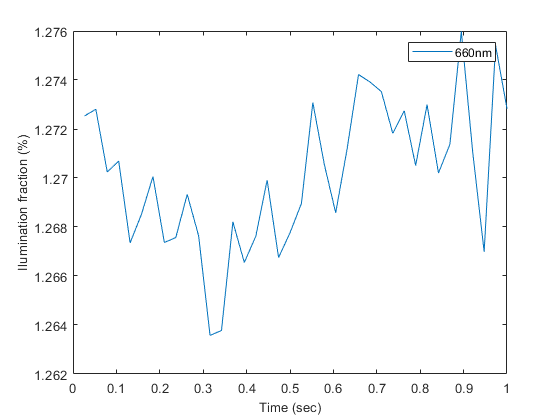

save('SPulse_660_02_1.mat','S')
T=1/38;
t=T:T:length(S)*T;
figure
plot(t,S)
ylabel('Ilumination fraction (%)', 'FontSize', 10)
legend("660nm");
xlabel('Time (sec)', 'FontSize', 10)

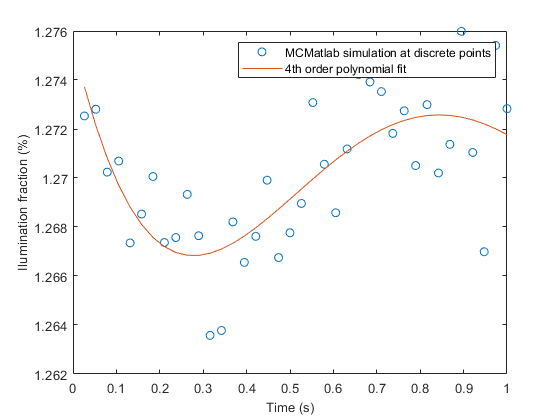

% Fig 7.10 Plotting
%load("SPulse_660_02_1.mat")
load("SPulse_660_001_1.mat")
T=1/38;
t=T:T:length(S)*T;
[xData, yData] = prepareCurveData( t, S );
% Set up fittype and options.
ft = fittype( 'poly4' );
% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

figure
plot(t,S,'o')
hold on
plot(t, fitresult(t) );
legend('MCMatlab simulation at discrete points','4th order polynomial fit')
ylabel('Ilumination fraction (%)', 'FontSize', 10)
xlabel('Time (s)', 'FontSize', 10)

disp('Percentage of the AC component is:')

Percentage of the AC component is:


100*(max(fitresult(t))-min(fitresult(t)))/max(fitresult(t))

ans = 0.5402

## Simulation of the airgap at different frequencies

% Fig 7.7 simulation
clear all
global zsurf;
global wave_l;
global B_Cutaneous;
B=[0.2037, 0.2454];
wavelen=[660, 940];
depth=[0.001, 0.01, 0.2, 0.3]; % 0.4 is too much

for j=1:2
for k=1:2
    for i=1:4;
    zsurf=depth(i);
    wave_l=wavelen(j);
    B_Cutaneous=B(k);
    clear_all_but('zsurf','wave_l','B_Cutaneous', 'i', 'j', 'k', 'S','depth','wavelen','B');
    Example4_BloodVessel_changeS_barrier1

    model = runMonteCarlo(model);
    
    plotMCmatlab(model);
    if model.MC.LC.res > 1
        detFraction = 100*mean(mean(sum(model.MC.LC.image,3)))*model.MC.LC.fieldSize^2;
    else
        detFraction = 100*sum(model.MC.LC.image,3);
    end  
    S(j,k,i)=detFraction;
end
end
end

-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating...  16% done
Ctrl+C detected, stopping.Error writing to output stream.
iostream stream error


Error using MCmatlab
Error writing to output stream.
iostream stream error


Error in runMonteCarlo (line 143)
    model = MCmatlab(model,simType);

save('SBarrier1.mat','S')

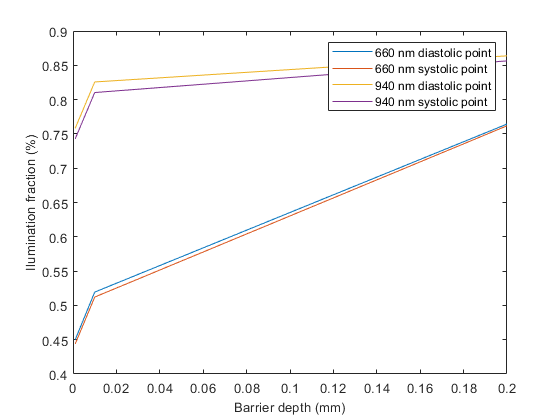

% Fig 7.7 plotting
load('SBarrier1.mat')
depth=[0.001, 0.01, 0.2, 0.3]; % 0.4 is too much
figure
N=3;
Dia660=reshape(S(1,1,:),[4,1]);
Sys660=reshape(S(1,2,:),[4,1]);
Dia940=reshape(S(2,1,:),[4,1]);
Sys940=reshape(S(2,2,:),[4,1]);
plot(depth(1:N),Dia660(1:N))
hold on
plot(depth(1:N),Sys660(1:N))
plot(depth(1:N),Dia940(1:N))
plot(depth(1:N),Sys940(1:N))
legend('660 nm diastolic point','660 nm systolic point','940 nm diastolic point','940 nm systolic point')
ylabel('Ilumination fraction (%)', 'FontSize', 10)
xlabel('Barrier depth (mm)', 'FontSize', 10)

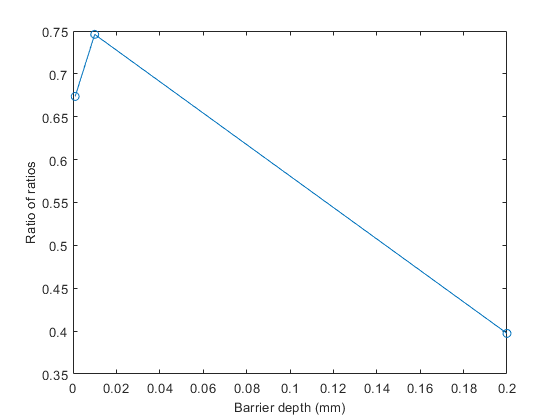


figure
plot(depth(1:N),((Dia660(1:N)-Sys660(1:N))./Dia660(1:N))./((Dia940(1:N)-Sys940(1:N))./Dia940(1:N)),'o-')
ylabel('Ratio of ratios', 'FontSize', 10)
xlabel('Barrier depth (mm)', 'FontSize', 10)

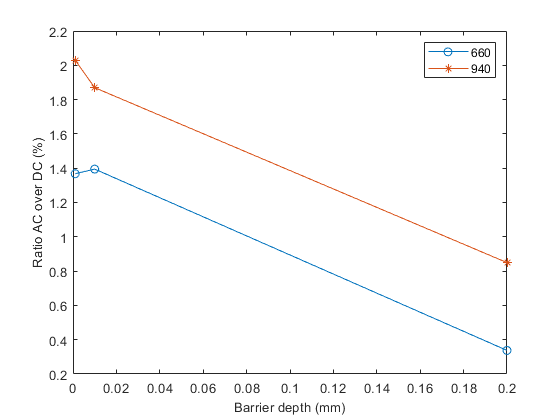


figure
plot(depth(1:N),100*((Dia660(1:N)-Sys660(1:N))./Dia660(1:N)),'o-')
hold on
plot(depth(1:N),100*((Dia940(1:N)-Sys940(1:N))./Dia940(1:N)),'*-')
legend('660','940')
ylabel('Ratio AC over DC (%)', 'FontSize', 10)
xlabel('Barrier depth (mm)', 'FontSize', 10)

## Plotting the normalized absorbed power and normalized fluence rate of collected light

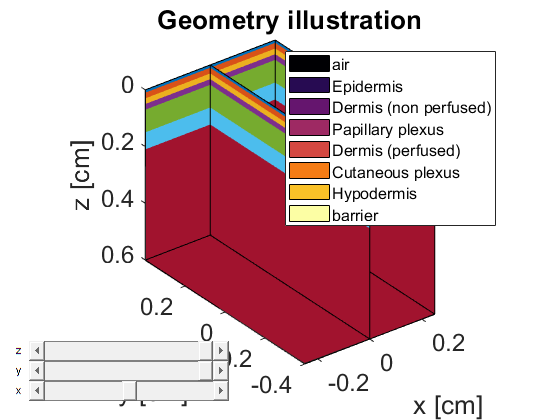

%Fig 7.3 and 7.8
clear all
global zsurf;
zsurf=0.01;
Example4_BloodVessel_Pulse

-----------------Monte Carlo Simulation------------------
Simulation duration = 5.000 min
Calculating... 100% done
Simulated 1.03e+07 photons at a rate of 2.06e+06 photons per minute


----------------------plotMCmatlab-----------------------


86.9% of incident light hits the cuboid boundaries.


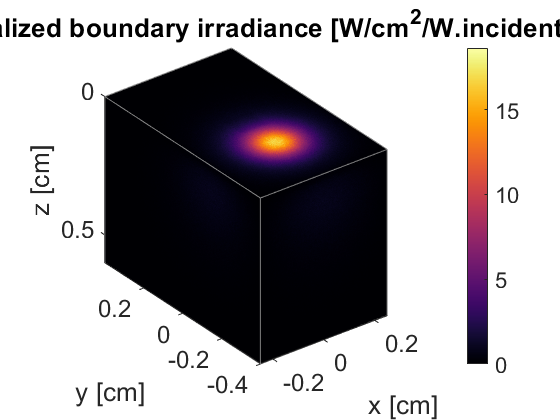

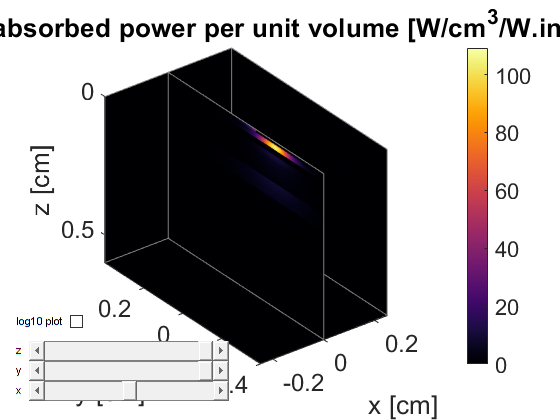

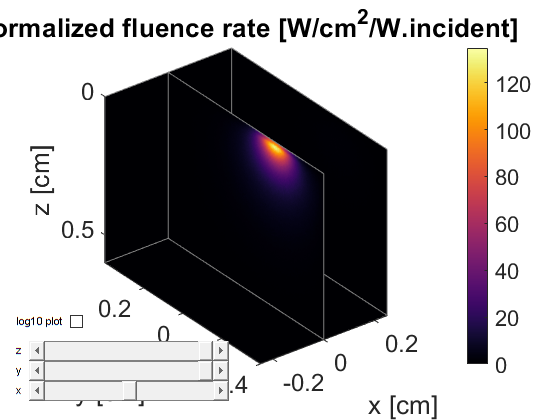

13.1% of incident light was absorbed within the cuboid.


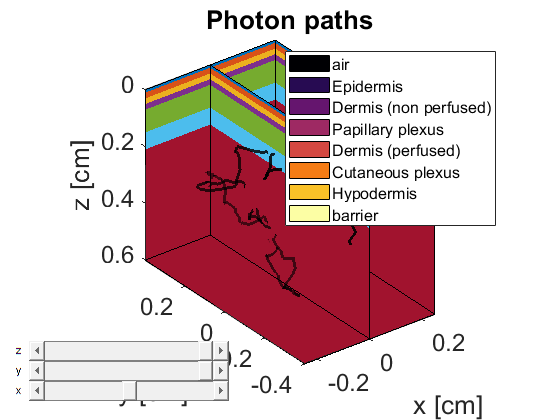

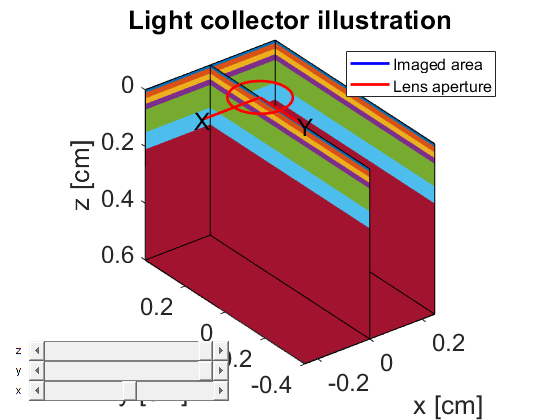

0.969% of incident light ends up on the detector.


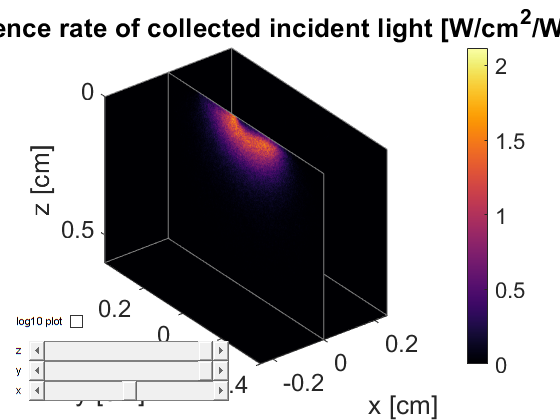

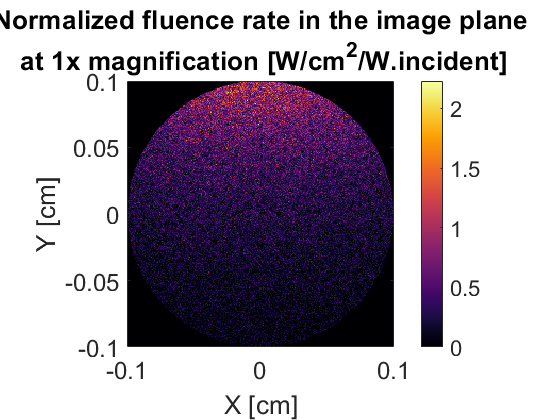

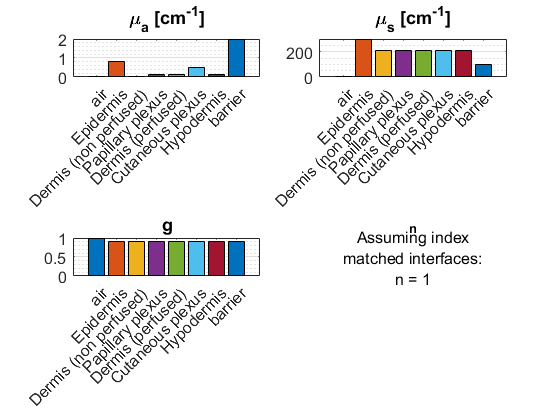


    model = runMonteCarlo(model);
    
    plotMCmatlab(model);
    if model.MC.LC.res > 1
        detFraction = 100*mean(mean(sum(model.MC.LC.image,3)))*model.MC.LC.fieldSize^2;
    else
        detFraction = 100*sum(model.MC.LC.image,3);
    end  
    S(i)=detFraction;


## Effects of air gap to the ratio of ratios

    % Fig 7.9 simulation
    clear all
global ii;
global wave_l;
global B_Cutaneous;
B=[0.2037, 0.2454];
wavelen=[660, 940];

for j=1:2
    for k=1:2    
        clear_all_but('wave_l','B_Cutaneous', 'i1', 'j', 'k', 'S','B','wavelen','ii');
        wave_l=wavelen(j);
        B_Cutaneous=B(k);
        ii=0.45;
        Example4_BloodVessel_changeS_new1
        for i1=1:11;
            
            ii=0.45+0.05*i1;

            model = runMonteCarlo(model);
            
            %plotMCmatlab(model);
            if model.MC.LC.res > 1
                detFraction = 100*mean(mean(sum(model.MC.LC.image,3)))*model.MC.LC.fieldSize^2;
            else
                detFraction = 100*sum(model.MC.LC.image,3);
            end
            
            S(j,k,i1)=detFraction;
        end
    end
end

-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.40e+07 photons at a rate of 2.40e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.34e+07 photons at a rate of 2.34e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.46e+07 photons at a rate of 2.46e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.36e+07 photons at a rate of 2.36e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.35e+07 photons at a rate of 2.35e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 

100% done
Simulated 2.48e+07 photons at a rate of 2.48e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.34e+07 photons at a rate of 2.34e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.32e+07 photons at a rate of 2.32e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.37e+07 photons at a rate of 2.37e+06 photons per minute


-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.77e+07 photons at a rate of 2.77e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.71e+07 photons at a rate of 2.71e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.66e+07 photons at a rate of 2.66e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.77e+07 photons at a rate of 2.77e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.67e+07 photons at a rate of 2.67e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 

-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.19e+07 photons at a rate of 3.19e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.37e+07 photons at a rate of 3.37e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating...  91% done

 92% done

100% done
Simulated 3.22e+07 photons at a rate of 3.22e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.09e+07 photons at a rate of 3.08e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.05e+07 photons at a rate of 3.05e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 2.97e+07 photons at a rate of 2.97e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.29e+07 photons at a rate of 3.29e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.36e+07 photons at a rate of 3.36e+06 photons per minute
--

-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.18e+07 photons at a rate of 3.18e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.44e+07 photons at a rate of 3.44e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.33e+07 photons at a rate of 3.33e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.25e+07 photons at a rate of 3.25e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 10.000 min
Calculating... 100% done
Simulated 3.43e+07 photons at a rate of 3.43e+06 photons per minute
-----------------Monte Carlo Simulation------------------
Simulation duration = 

save('SChange.mat','S')
test=1;

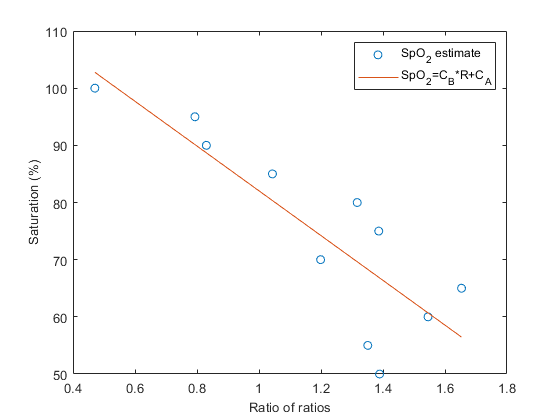

% Fig 7.9 plotting
load('SChange.mat')
SpO2=50:5:100;
RatioOfRatios=((reshape(S(1,2,:),[11,1])-reshape(S(1,1,:),[11,1]))./reshape(S(1,2,:),[11,1]))./((reshape(S(2,2,:),[11,1])-reshape(S(2,1,:),[11,1]))./reshape(S(2,2,:),[11,1]));
%% Fit: 'untitled fit 1'.
p = polyfit(RatioOfRatios',SpO2,1);
y1 = polyval(p,RatioOfRatios');
figure
plot(RatioOfRatios,SpO2,'o')
hold on
plot(RatioOfRatios,y1,'-')
xlabel('Ratio of ratios', 'FontSize', 10)
ylabel('Saturation (%)', 'FontSize', 10)
legend('SpO_2 estimate','SpO_2=C_B*R+C_A')

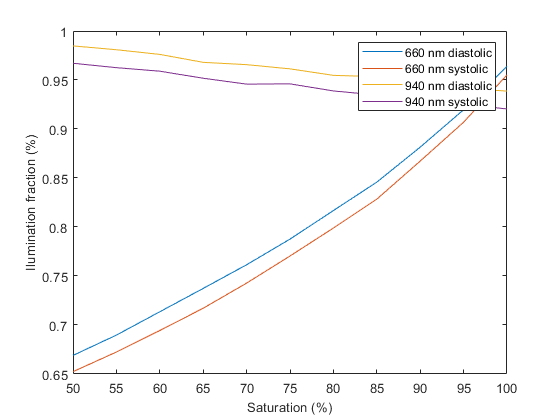

figure
plot(SpO2,reshape(S(1,1,:),[11,1]))
hold on
plot(SpO2,reshape(S(1,2,:),[11,1]))
plot(SpO2,reshape(S(2,1,:),[11,1]))
plot(SpO2,reshape(S(2,2,:),[11,1]))
legend('660 nm diastolic','660 nm systolic','940 nm diastolic','940 nm systolic')
ylabel('Ilumination fraction (%)', 'FontSize', 10)
xlabel('Saturation (%)', 'FontSize', 10)